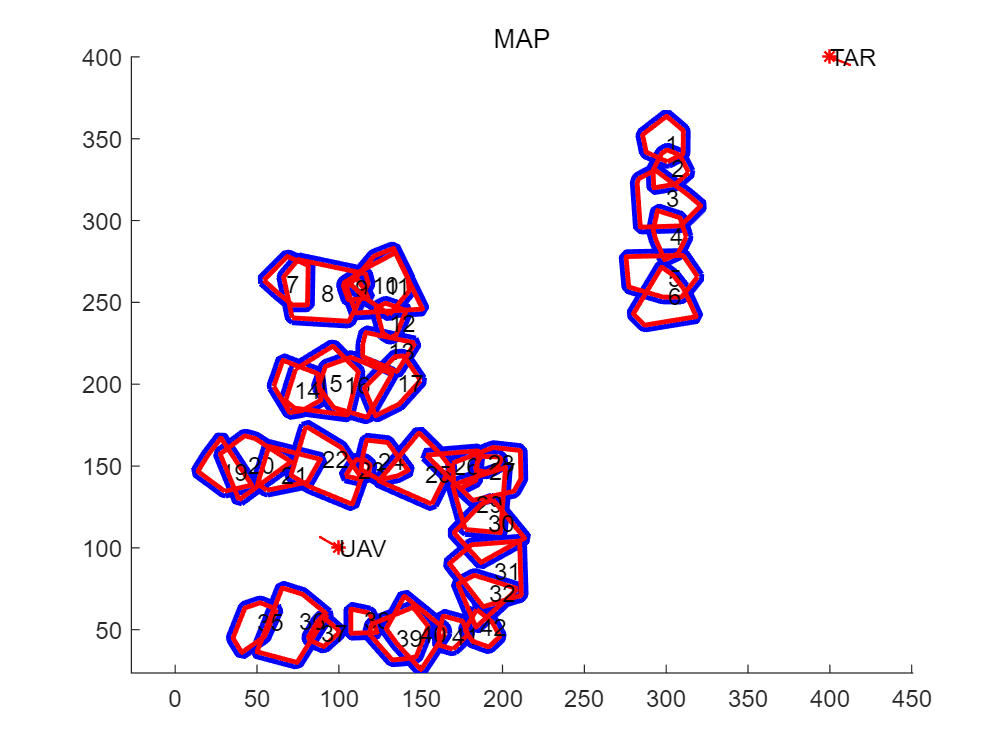

clear all
clf 
%% 定义函数输入
r=7;%最小转弯半径
Stepsize=0.01;%路径的生成间隔

sure=3;%保证安全的预留距离
% R=10+sure;


mapsize=400;
num=0;%%%%随机障碍物数量
R=[10,30];%%%障碍物半径范围;
num_obs_nocircle=5;
num_steps=100;%%%%边界上几个点
% Start_Point = [100,0,-pi/6];
% End_Point = [200,200,-pi/2];%[x,y,角度]

% Start_Point = [round(rand(1,2)*mapsize),-pi+rand(1)*2*pi];
% End_Point = [round(rand(1,2)*mapsize),-pi+rand(1)*2*pi];%[x,y,角度]

Start_Point = [100,100,-pi+rand(1)*2*pi];
End_Point = [200,200,-pi+rand(1)*2*pi];%[x,y,角度]

outline_all=[];
center=[            110,190;
                  90,170;  130,170; 
               70,150;        140,150;
             50,140;             150,140;
          30,120;                  160,120;
        10,100;                       170,100;
                                    160,90;
                                   150,80;
                                  140,70;
                                 130,60;
                                120,50;

         ];

for i=1:length(center(:,1))
    [outline,vertex,expandedPolygon]=obtain_obs_nocircle_hand(center(i,:)',mapsize,R,num_steps,Start_Point,End_Point,sure);
    if ~isempty(outline)
        outline=[outline,ones(length(outline(:,1)),1)*i];
        outline_all=[outline_all;outline];
        obs_no_circle{i}=expandedPolygon;
        obs_no_circle_in{i}=vertex;
    end
end









% [outline_all,obs_no_circle,obs_no_circle_in]=obtain_obs_no_circle_all(num_obs_nocircle,mapsize,R,num_steps,Start_Point,End_Point,sure);

% total_field=obtian_field(mapsize+R(2)+sure,End_Point,outline_all,k_att,k_rep,r_search);
[obs,obs_no_circle,obs_no_circle_in,outline_all]=obtain_map(num,mapsize,Start_Point, End_Point,R,r,obs_no_circle,obs_no_circle_in,outline_all);%[x,y,障碍物的安全半径R]


r_search=15;%%探测半径
k_att=1.5;%计算引力需要的增益系数
k_rep=30;%计算斥力的增益系数，都是自己设定的。


% load("0317_2.mat") 
total_field=obtian_field(mapsize+R(2)+sure,End_Point,outline_all,k_att,k_rep,r_search);
Draw_map(Start_Point,End_Point,obs,sure,obs_no_circle,obs_no_circle_in);%绘制地图


tic
[final_path,open,close]=A_dubins_nocircle_no_father(Start_Point,End_Point,obs,sure,r,obs_no_circle,obs_no_circle_in,outline_all,Stepsize,total_field);

from           -1                  avoid  10
1
1.1
directly find 1-2 safe
1.2
directly find 1-2 safe
from           -1                  avoid  11
1
1.1
directly find 1-2 safe
from           -1                  avoid  12
1
1.1
directly find 1-2 safe
1.2
directly find 1-2 safe
from           -1                  avoid  15
1
1.1
directly find 1-2 safe
from           -1                  avoid  16
1
1.1
directly find 1-2 safe
1.2
directly find 1-2 safe
from           -1                  avoid  22
1
from           -1                  avoid  25
2
type 2
2 succed 1
directly find 1-2 safe
2 succed 2
directly find 1-2 safe
from           11                  avoid  1
3
type 2
3 succed 1
directly find 1-2 safe
3 succed 2
directly find 1-2 safe
from           11                  avoid  18
1
1.1
directly find 1-2 safe
1.2
directly find 1-2 safe
from           11                  avoid  21
1
1.1
directly find 1-2 safe
1.2
directly find 1-2 safe
from           10                  avoid  11
1
1.1
direct

toc

历时 29.152110 秒。


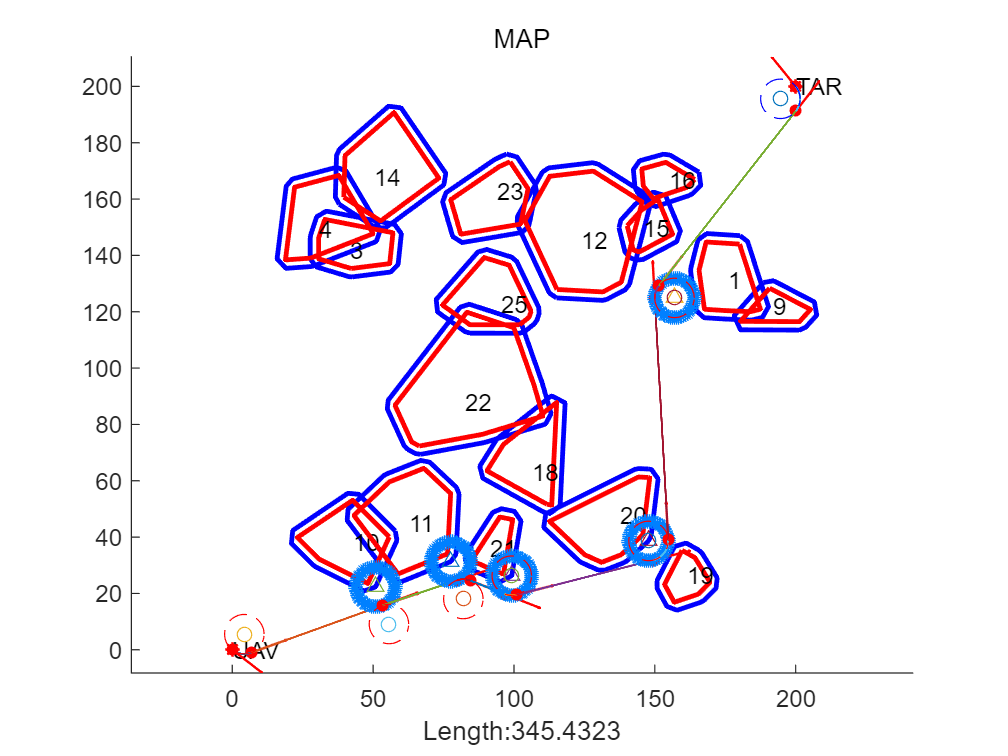

figure
Draw_map(Start_Point,End_Point,obs,sure,obs_no_circle,obs_no_circle_in);%绘制地图
Draw_pathA_no_circle(final_path);
hold off

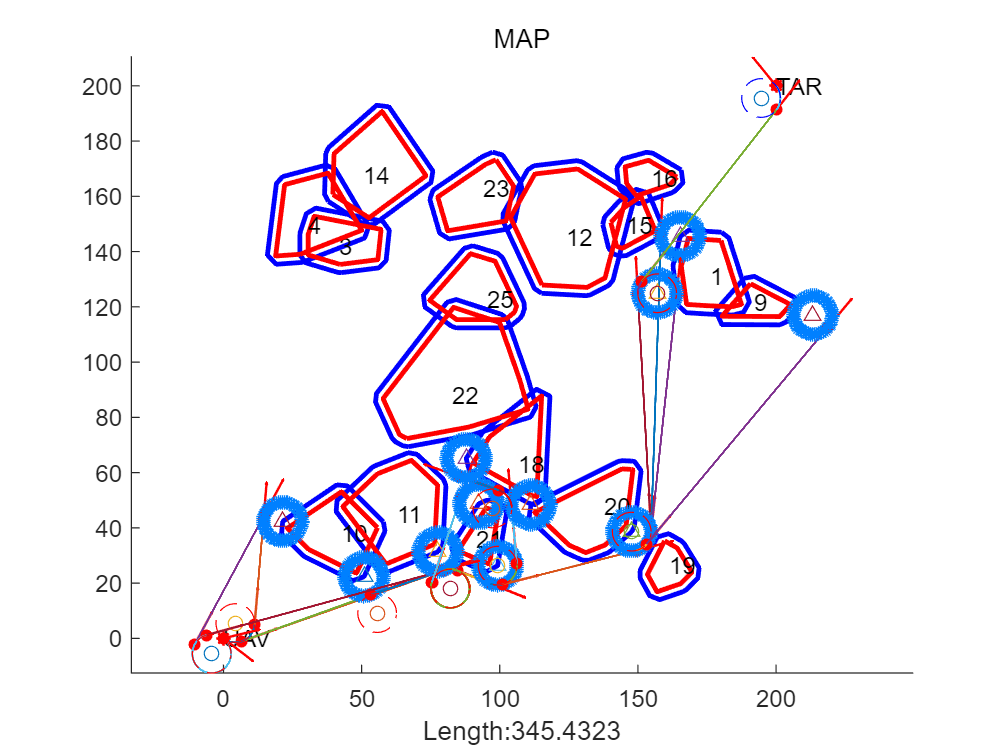

figure

Draw_map(Start_Point,End_Point,obs,sure,obs_no_circle,obs_no_circle_in);%绘制地图
Draw_pathA_no_circle(close);                    
Draw_pathA_no_circle_open_close(open);
hold off


[draw_path,vtheta_all]=obtain_vtheta_drawpath_nocircle(final_path);

